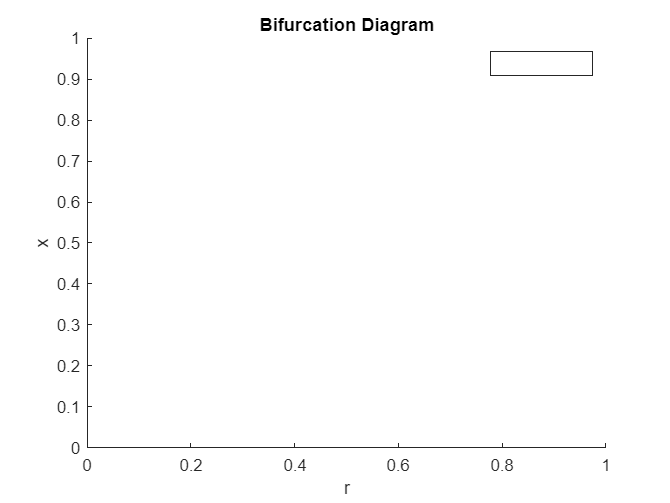

% Define symbolic variables
syms x r
assume(x, 'real')

% Define your function here
fx1 = r*x + (x^3)/(1+x^2);
fx2 = 1 + r*x + x^2;
fx3 = r + x - log(1+x);

% Compute the derivative once
df = diff(fx1, x);

% Convert symbolic functions to anonymous functions for faster evaluation
f_anon = matlabFunction(fx1, 'Vars', [r, x]);
df_anon = matlabFunction(df, 'Vars', [r, x]);

% Call the GUI function and pass the function
%varying_parameter_window(f_anon, df_anon, r, x);
bifurcation_diagram(f_anon, df_anon);


%plotTrajectories(fx1);
